% Let's set up a three segment system:
N = 5;
sym_mat_twists = zeros(3, N, "sym");
for i = 1:N
    sym_mat_twists(:, i) = sym([sprintf("v_x%d", i); sprintf("v_y%d", i); sprintf("omega_%d", i)]);
end
assume(sym_mat_twists, "real")

Q = sym(["Q_1"; "Q_2"; "Q_3"]);
assume(Q, "real")

g_0 = Pose2.hat(sym(["x_0", "y_0", "theta_0"]));
assume(g_0, "real");
q = calc_external_wrench(sym_mat_twists, Q, g_0);

v_q = q(:);
v_twists = sym_mat_twists(:);

J = jacobian(v_q, v_twists);
%J = simplify(J);

J

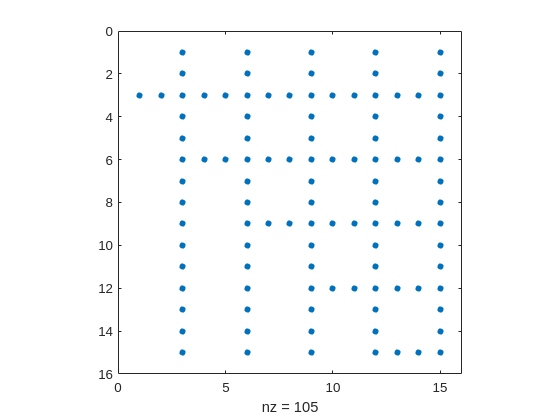

figure()
spy(J)

tic
matlabFunction(J, "File", sprintf("J_external_%dseg", N), "Vars", {theta_0, Q, sym_mat_twists});
toc

Elapsed time is 324.210598 seconds.
